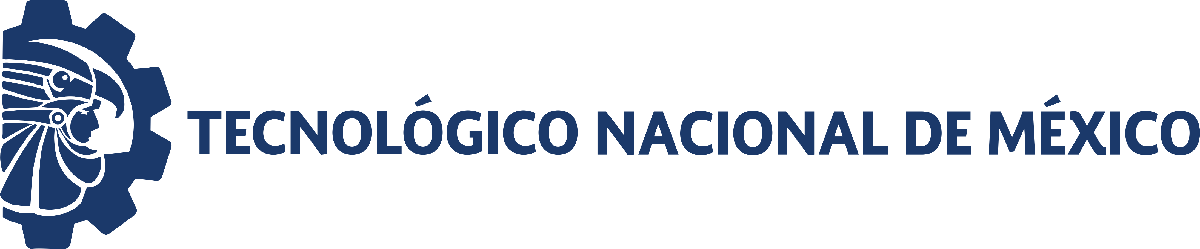                                 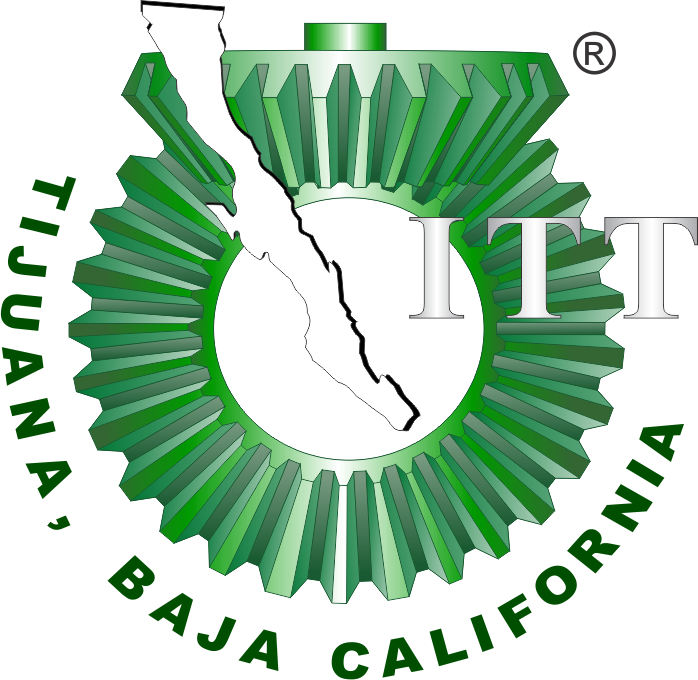

# Proyecto: Sistema Urinario

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## 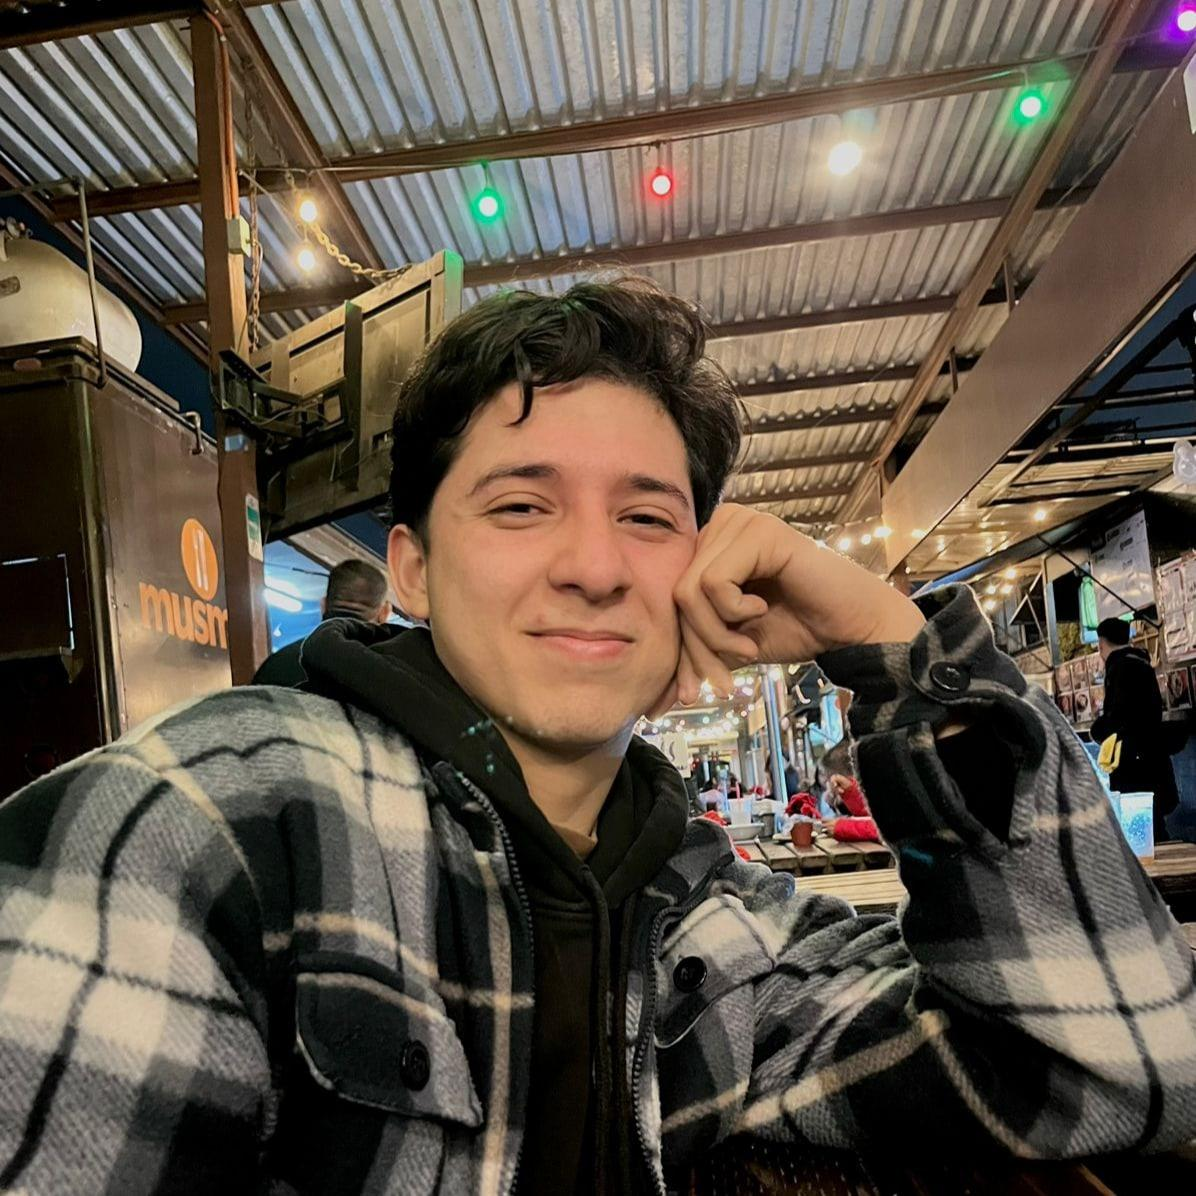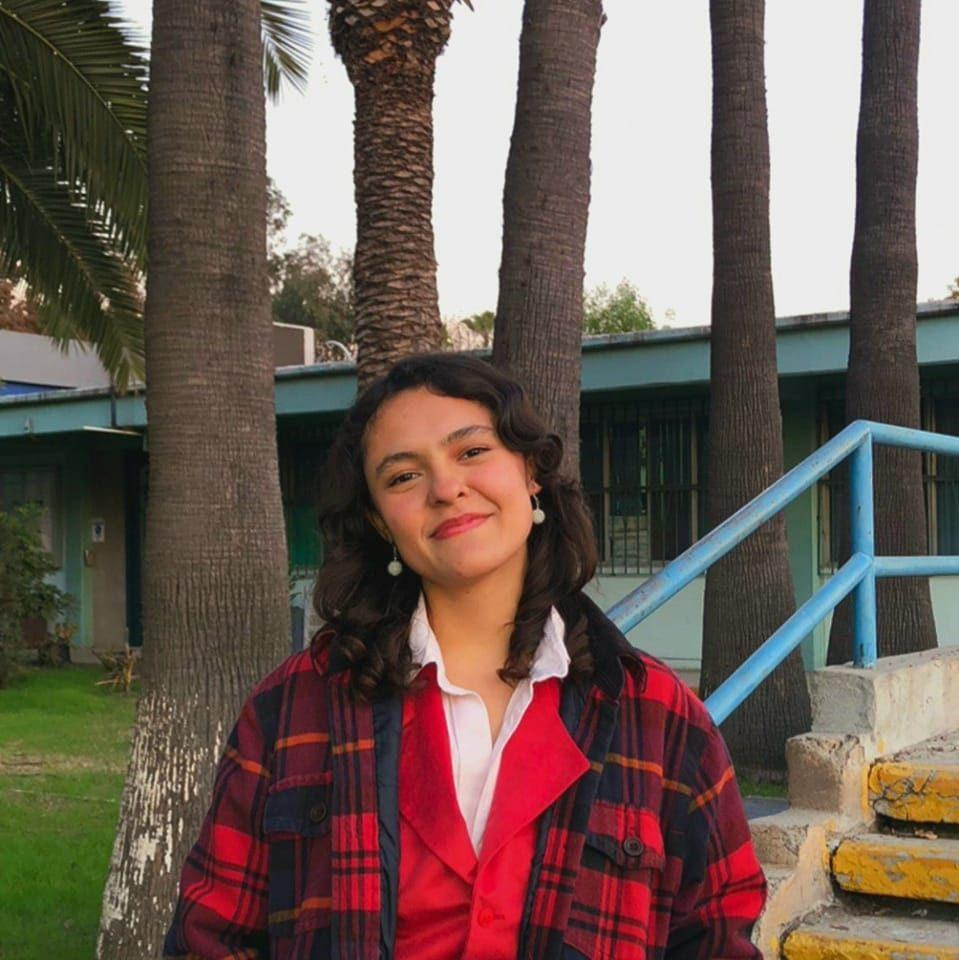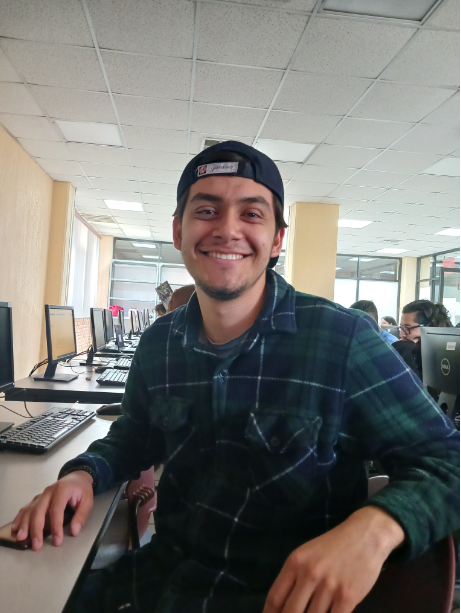

## Información general

Nombre del alumno: **Marla Espinoza Bedoy, Abraham Gómez Aguilar, Jesus Zamora Cervantes **

Número de control: **21212152, 21212158, 21212185**

Correo institucional: **l21212152@tectijuana.edu.mx, l21212158@tectijuana.edu.mx, l21212185@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'PROYECTO_SIMULINK';
open_system(file);
parameters.StopTime=tend;
parameters.Solver = 'ode45';
Controlador= 'I';

## Parámetros del controlador y rendimiento


$$\begin{array}{l}
K_p =0\\
K_I =1317\ldotp 4583\\
K_D =0\\
\textrm{Rise}\;\textrm{time}=0\ldotp 00539s\\
\textrm{Settling}\;\textrm{time}=0\ldotp 013\;s\\
\textrm{Overshoot}=0%\\
\textrm{Peak}=0\ldotp 999\;V
\end{array}$$


## Respuesta a la impulso

## Respuesta a la función Impulso

### **Contracción normal **

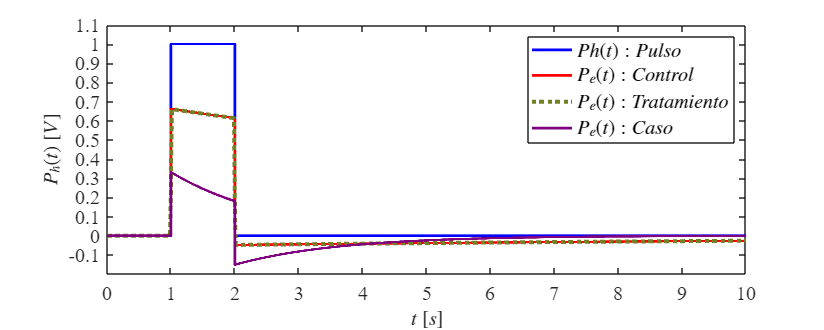

set_param('PROYECTO_SIMULINK/I Controller','I', '1317.4583');
Signal = 'Sistema Urinario';
N= sim(file, parameters);

% Llamada a la función para graficar
plotsignals(N.t, N.Ph, N.Pex, N.Pez, N.Pey, Signal);

## Funciones 

function plotsignals(t,Ph,Pex,Pez,Pey,Signal)
set(figure(), 'Color','w')
set(gcf, 'units','centimeters', 'position',[1,5,30,12])
set(gca,'FontName', 'Times New Roman', 'FontSize', 15)
hold on; grid off; box on

plot (t,Ph,'LineWidth',2,'Color',[0,0,1]) %Azul
plot (t,Pex,'LineWidth',2,'Color',[1,0,0])  %Rojo
plot(t,Pez,':','LineWidth',3,'Color', [0.45,0.5,0.15]) %Verde
plot(t,Pey,'LineWidth',2,'Color', [0.5,0,0.5]) %Morado


L = legend('$Ph(t):Pulso$', '$P_{e}(t):Control$', '$P_{e}(t):Tratamiento$','$P_{e}(t):Caso$');
set(L,'Interpreter','Latex','FontSize',15,'Location','NorthEast','Box','On')


xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',15)
ylabel('$P_h(t)$ $[V]$','Interpreter','Latex', 'FontSize',15)
xlim([0,10]); xticks(0:1:10)
ylim([-0.2,1.1]); yticks(-0.1:0.1:1.1)


exportgraphics(gcf,[Signal,'.pdf'], 'ContentType','vector')
exportgraphics(gcf,[Signal,'.png'],'Resolution',600);
print(Signal,'-dsvg','-r600');
print(Signal,'-dsvg','-r600');

end
